# Project 2

**Name: Joshua Jackson**

**Date: 10/7/2022**

**Table of Contents:**

Problem Statement

Part I: Comparison of the bracketing methods

Part II: Comparison of the open methods

Part III: Using the Muller method

Part IV: Using found roots

Part V: Using the Quadratic Formula

Part VI: Verifying Results

Observations and conclusions

## **Problem Statement: **

The acidity of a solution of magnesium hydroxide in hydrochloric acid can be obtained using the following equation: 

A(x) = x^3 + 3.5x^2 -40

where x is the hydronium ion concentration.  A chemical engineer is trying to find the hydronium ion concentration for a  saturated solution (acidity equals zero).

## **Part I: Comparison of the bracketing methods **

Find a root x in the range of [0,10]. Use 0.1% as the stopping criterion and 100 as the maximum # of iterations. 

a) Using the Bisection method

% Initial guesses
xl = 0;
xu = 10; 

% Define f(N) using anonymous function so that N will be the solution of equation f(N)=0
f = @(x) (x^3 + 3.5 * x^2 - 40);


% Call function myBisect to obtain N
[x, ea] = myBisect(f, xl, xu, 0.1, 100)

     0    10     5   100

         0    5.0000    2.5000  100.0000

    2.5000    5.0000    3.7500   33.3333

    2.5000    3.7500    3.1250   20.0000

    2.5000    3.1250    2.8125   11.1111

    2.5000    2.8125    2.6562    5.8824

    2.5000    2.6562    2.5781    3.0303

    2.5000    2.5781    2.5391    1.5385

    2.5391    2.5781    2.5586    0.7634

    2.5586    2.5781    2.5684    0.3802

    2.5586    2.5684    2.5635    0.1905

    2.5635    2.5684    2.5659    0.0951



x = 2.5659

ea = 0.0951

% Function myBisect is at end of code
es = 0.1;
imax = 100; 

**Bisection results description:** Using the bisection method to find the root of an equation yielded a result of x = 2.5659 with an error of 0.0951%. 

b) Using the False Position method

% Initial guesses
xl = 0;
xu = 10; 

% Define f(N) using anonymous function so that N will be the solution of equation f(N)=0
f = @(x) (x^3 + 3.5 * x^2 - 40);


% Call function myFalsePosition to obtain N
[x, ea] = myFalsePosition(f, xl, xu, 0.1, 100)

   1.0e+03 *

         0    0.0100    0.0003    3.2750

    0.2963   10.0000    0.5815   49.0452

    0.5815   10.0000    0.8512   31.6863

    0.8512   10.0000    1.1015   22.7231

    1.1015   10.0000    1.3293   17.1370

    1.3293   10.0000    1.5327   13.2699

    1.5327   10.0000    1.7110   10.4206

    1.7110   10.0000    1.8647    8.2413

    1.8647   10.0000    1.9951    6.5383

    1.9951   10.0000    2.1044    5.1919

    2.1044   10.0000    2.1948    4.1214

    2.1948   10.0000    2.2690    3.2686

    2.2690   10.0000    2.3293    2.5892

    2.3293   10.0000    2.3780    2.0486

    2.3780   10.0000    2.4171    1.6190

    2.4171   10.0000    2.4484    1.2782

    2.4484   10.0000    2.4734    1.0082

    2.4734   10.0000    2.4932    0.7947

    2.4932   10.0000    2.5089    0.6260

    2.5089   10.0000    2.5213    0.4929

    2.5213   10.0000    2.5311    0.3879

    2.5311   10.0000    2.5389    0.3052

    2.5389   10.0000    2.5450    0.2401

    2.5450   10.0000

x = 2.5589

ea = 0.0918

% Function myFalsePosition is at end of the code
es = 0.1;
imax = 100;

**False Position results description: **Using the false position method to find the root of an equation yielded a result of x = 2.5589 with an error of 0.0918%. 

## **Part II: Comparison of the open methods **

Find a root using 0.1% as the stopping criterion and 100 as the maximum # of iterations. 

a. Using the Newton Raphson method with initial guess 0. If it diverges try initial guess 10

% Initial guess: 0
x0 = 0;

f = @(x) (x^3 + 3.5 * x^2 - 40);

dfdx = @(x) (3*x^2 + 7 * x);

es = 0.1; 
imax = 100;

% Call function myNewRaph
[x, ea] = myNewRaph(f, dfdx, x0, es, imax)

     0   Inf   NaN

   Inf   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN

   NaN   NaN   NaN



x = NaN

ea = NaN

% Initial guess: 10
x0 = 10;

f = @(x) (x^3 + 3.5 * x^2 - 40);

dfdx = @(x) (3*x^2 + 7 * x);

es = 0.1;
imax = 100;

% Call function myNewRaph
[x, ea] = myNewRaph(f, dfdx, x0, es, imax)

   10.0000    6.4595   54.8117

    6.4595    4.2554   51.7954

    4.2554    3.0613   39.0053

    3.0613    2.6276   16.5078

    2.6276    2.5686    2.2945

    2.5686    2.5676    0.0406



x = 2.5686

ea = 0.0406

**Newton-Raphson results description:** Using the Newton-Raphson method to find the root of an equation yielded no result with an initial guess of 0 because equation diverged. Starting with an initial guess of 10, the Newton-Raphson method yielded a result of x = 2.5686 with an error of 0.0406%. 

b. Using the modified Secant method (delta = 0.01) with initial guess 0. If it diverges, try initial guess 10. 

% Initial guess 0
xi = 0;

% Define f(N) using anonymous function so that N will be the solution of equation f(N)=0
f = @(x) (x^3 + 3.5 * x^2 - 40);

% Call function mySecant2 to obtain N, use delta = 0.01
[x, ea] = mySecant2(f, xi, 0.01, 0.1, 100)

    0.0100  566.1522   99.9982

  566.1522  378.9222   49.4112

  378.9222  253.4831   49.4862

  253.4831  169.4429   49.5979

  169.4429  113.1399   49.7641

  113.1399   75.4212   50.0107

   75.4212   50.1555   50.3746

   50.1555   33.2364   50.9052

   33.2364   21.9154   51.6581

   21.9154   14.3561   52.6560

   14.3561    9.3386   53.7274

    9.3386    6.0665   53.9385

    6.0665    4.0426   50.0641

    4.0426    2.9745   35.9069

    2.9745    2.6124   13.8611

    2.6124    2.5685    1.7102

    2.5685    2.5676    0.0356



x = 2.5685

ea = 0.0356


% Function mySecant2
es = 0.1;
imax = 100;
delta = 0.01;



% Initial guess 10
xi = 10;

% Define f(N) using anonymous function so that N will be the solution of equation f(N)=0
f = @(x) (x^3 + 3.5 * x^2 - 40);

% Call function mySecant2 to obtain N, use delta = 0.01
[x, ea] = mySecant2(f, xi, 0.01, 0.1, 100)

    0.0100  566.1522   99.9982

  566.1522  378.9222   49.4112

  378.9222  253.4831   49.4862

  253.4831  169.4429   49.5979

  169.4429  113.1399   49.7641

  113.1399   75.4212   50.0107

   75.4212   50.1555   50.3746

   50.1555   33.2364   50.9052

   33.2364   21.9154   51.6581

   21.9154   14.3561   52.6560

   14.3561    9.3386   53.7274

    9.3386    6.0665   53.9385

    6.0665    4.0426   50.0641

    4.0426    2.9745   35.9069

    2.9745    2.6124   13.8611

    2.6124    2.5685    1.7102

    2.5685    2.5676    0.0356



x = 2.5685

ea = 0.0356


% Function mySecant2
es = 0.1;
imax = 100;
delta = 0.01;

**Modified Secant results description:** Using the modified secant method to find the root of an equation with an initial guess of 0 yielded a result of x = 2.5685 with an error of 0.0356%. Using this same method with an initial guess of 10 yielded the same result of x = 2.5685 with an error of 0.0356%. 

## **Part III: Using the Muller method** 

Use the Muller method to find a root of the polynomial with initial guesses x0 = 0, x1 = 5, x2 = 10

Find the root using 0.1% as the stopping criterion and 100 as themaximum # of iterations

% Initial guesses
x0 = 0;
x1 = 5;
x2 = 10;

% Define f(x) using anonymous function
f = @(xM) (xM^3 + 3.5 * xM^2 - 40);

es = 0.1;
imax = 100;

% Call function
[xM, ea] = myMuller(f, x0, x1, x2, es, imax)

   10.0000    3.3484  198.6477

   3.3484 + 0.0000i   2.2937 - 0.7557i  53.7292 + 0.0000i

   2.2937 - 0.7557i   2.6369 + 0.1072i  35.1893 + 0.0000i

   2.6369 + 0.1072i   2.5663 + 0.0017i   4.9464 + 0.0000i

   2.5663 + 0.0017i   2.5676 - 0.0000i   0.0826 + 0.0000i



xM = 2.5676 - 0.0000i

ea = 0.0826

**Muller results description: **Using the Muller method to find the root of an equation yielded a result of x = 2.5589 with an error of 0.0918%. 

## **Part IV: Using found roots**

Using the root obtained with any of the methods from Step 1-3, in 5 significant figures, determine the factorized version of 

A(x) = x^3 + 3.5x^2 - 40

Suppose x = t, the factorized version of A(x) is

A(x) = (x - t)(a2x^2 + a1x + a0)

Write a MATLAB function called myPolyDef to implement the pseudocode and call the function to determine a2, a1, a0. 

% Call the function myPolyDef
pol = myPolyDef([-40 0 3.5 1], 2.5685)

pol =    15.5869    6.0685    1.0000         0


% Assign Values to a2, a1, a0 for use in quadratic formula
a0 = pol(1,1)

a0 = 15.5869

a1 = pol(1,2)

a1 = 6.0685

a2 = pol(1,3)

a2 = 1

## **Part V**: **Using the Quadratic Formula**

With a2, a1, a0 obtained from step 4, the other two roots can be found by simply using the quadratic formula.

Write a MATLAB script to determine those roots. 

% Code to use quadratic formula to find roots
root1 = (-a1 + sqrt((a1)^2-4*a2*a0))/(2*a2);
root2 = (-a1 - sqrt((a1)^2-4*a2*a0))/(2*a2);

% Display the values of these two new roots
root1

root1 = -3.0343 + 2.5259i

root2

root2 = -3.0343 - 2.5259i

## **Part VI**: **Verifying Results**

Verify your results graphically and using the MATLAB built-in functions.

a. Plot A(x) = x^3 + 3.5x^2 - 40 versus x = 0:0.1:10. Put on grid and observe where the function curve crosses 0. Does it match your real root from Steps 1-3?

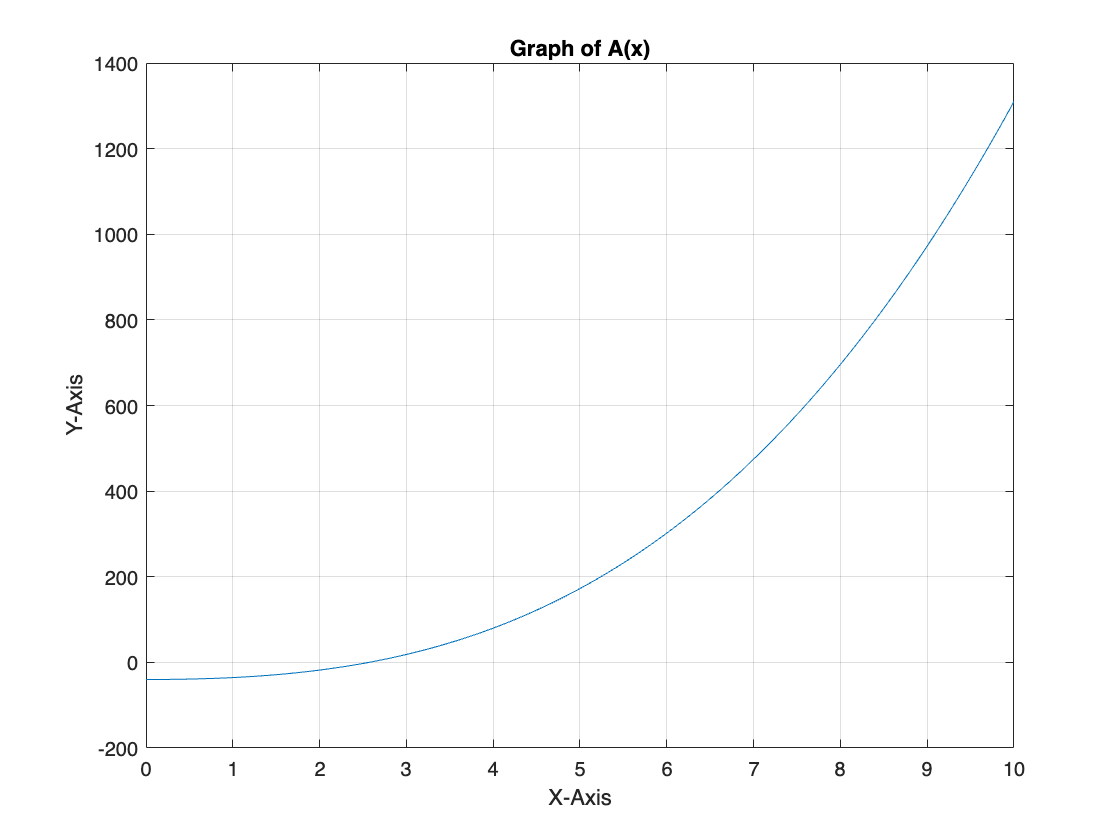

% Increment x from 0 to 10 with increments of 0.01
x = 0:0.01:10;

% Write code for equation 
y = x.^3 + 3.5*x.^2 - 40;

% Graph these x and y values
plot(x,y)

% Format the graph
grid on
xlabel("X-Axis")
ylabel("Y-Axis")
title("Graph of A(x)")

b. Call the MATLAB built-in function "roots" to find all three roots of A(x)

% Use MATLAB built-in function to find the roots of A(x)
roots([1 3.5 0 -40])

ans =   -3.0338 + 2.5249i
  -3.0338 - 2.5249i
   2.5676 + 0.0000i


## **Observations and Conclusions: **

Completing this project grew my understanding in many areas. I was able to grow in my understanding of the differing ways to compute the roots of an equation. I also gained a deeper understanding of how MATLAB can be effectively used to find this roots using the methods above. With a specified stopping criterion, the estimated roots that result from the methods used are extremely close in value to the real roots of the polynomial. This project opened my eyes to the capabilities of MATLAB and I look forward to continue to grow in understanding how to use MATLAB in many effective ways. 

Although the different methods used above to determine the roots of a polynomial are effective and quite exact in their results, the MATLAB built-in function named 'roots' is ultimately the quickest and most effective way to determine the roots of an equation. 

## **Functions**: 

function [a] = myPolyDef(a, t)

n = length(a)-1;
r = a(n+1);
a(n+1) = 0;

    for i = n: -1: 1
        s = a(i);
        a(i) = r;
        r = s + r * t;
    end  

end



function [x, ea] = myFalsePosition (f, xl, xu, es, imax)

    fl = f(xl); 
    fu = f(xu);
    xr = xu;
    for i = 1 : imax
        xrold = xr;
        xr = (xl*fu-xu*fl)/(fu-fl); 
        fr = f( xr );
        if xr ~= 0
            ea = abs(( xr - xrold )/ xr) * 100;
        end 
        disp([xl xu xr ea])
        test = fr; 
        if test < 0
            xl = xr;
            fl = fr;
        elseif test > 0 
                xu = xr;
                fu = fr;
        else
            ea = 0;
        end
        if ea < es
            break
        end
    end
    x = xr; 


end 



function [x, ea] = myBisect (f, xl, xu, es, imax )
  
    fl = f(xl); 
    xr = xu;
    for i = 1 : imax
        xrold = xr;
        xr = ( xl + xu )/2.0; 
        fr = f( xr );
        if xr ~= 0
            ea = abs(( xr - xrold )/ xr) * 100;
        end 
        disp([xl xu xr ea])
        test = fl*fr; 
        if test < 0
            xu = xr;
        elseif test > 0 
                xl = xr;
                fl = fr;
        else
            ea = 0;
        end
        if ea < es
            break
        end
    end
    x = xr;
end     



function [x, ea] = myNewRaph( f, dfdx, x0, es, imax )
    xr = x0;
    for i = 1: imax
        xrold = xr;
        xr = xrold - f(xrold)/dfdx(xrold);
        if xr ~= 0
            ea = abs(( xr - xrold )/ xr) * 100;
        end 
        disp([xrold xr ea]);
        if ea < es
            break
        end
    x = xr;
    end
end



function [x, ea] = mySecant2( f, xi, delta, es, imax )
    xp = xi;
    xr = delta;
    for i = 1: imax
        xp = xr;
        xr = xp - f(xp)*(delta*xp) /(f(xp+xp*delta)-f(xp)); %Modified Secant formula
        if xr ~= 0
            ea = abs(( xr - xp )/ xr) * 100;
        end 
        disp([xp xr ea]);
        if ea < es
            break
        end
    x = xr;
    end
end



function [xM, ea] = myMuller(f, x0, x1, x2, es, imax)
    for i = 1: imax
        h0 = x1 - x0;
        h1 = x2 - x1;
        d0 = (f(x1)-f(x0))/h0;
        d1 = (f(x2)-f(x1))/h1;
        a = (d1-d0)/(h1+h0);
        b = a*h1 + d1;
        c = f(x2);
        rad = sqrt(b^2-4*a*c);
        if abs(b+rad) > abs(b-rad)
           den = b + rad;
        else
           den = b - rad;
        end
        xr = x2 -2*c/den;
        if xr ~= 0
            ea = abs(( xr - x2 )/ xr) * 100;
        end 
        disp([x2 xr ea]);
        if ea < es
            break
        end
    x0 = x1;
    x1 = x2;
    x2 = xr;
    end
    xM = xr;
end


